`conn = database(datasource,username,password,driver,url)`

javaaddpath sqlite-jdbc-3.36.0.3.jar
conn = database('sqlite','','','org.sqlite.JDBC','jdbc:sqlite:C:\Users\kabil\OneDrive - Drexel University\Academic Years\3 - Pre-Junior\1 - Fall Quarter\BMES 375\bmes375.TonyOkeke.tko35\HW4\weightdata.sqlite')

conn =   connection with properties:

                  DataSource: 'sqlite'
                    UserName: ''
                      Driver: 'org.sqlite.JDBC'
                         URL: 'jdbc:sqlite:C:\Users\kabi ...'
                     Message: ''
                        Type: 'JDBC Connection Object'
  Database Properties:

                  AutoCommit: 'on'
                    ReadOnly: 'off'
                LoginTimeout: 0
      MaxDatabaseConnections: 0

  Catalog and Schema Information:

              DefaultCatalog: ''
                    Catalogs: {}
                     Schemas: {}

  Database and Driver Information:

         DatabaseProductName: 'SQLite'
      DatabaseProductVersion: '3.27.2'
                  DriverName: 'SQLite JDBC'
               DriverVersion: '3.27.2.1'


fetch(conn, 'SELECT * FROM patient')

ans = 250×12 table
    id    age      gender      height    initweight    calintake     jobstatus      timecardio    timeresist    sleep     steps     deltaweight
    __    ___    __________    ______    __________    _________    ____________    __________    __________    ______    ______    ___________
     1    19     {'Female'}    59.373      137.11       1967.8      {'Inactive'}      39.166        3.5163      9.0446    3311.9      0.14471  
     2    19     {'Female'}    82.672      154.96         1885      {'Inactive'}      37.615        1.2296      8.7172    3693.9       8.1381

Use Fetch() return a cell array

sqlquery = 'SELECT * FROM patient';
results = fetch(conn,sqlquery)

results = 250×12 cell array
    {[  1]}    {[19]}    {'Female'}    {[59.3734]}    {[137.1087]}    {[1.9678e+03]}    {'Inactive'}    {[39.1656]}    {[ 3.5163]}    {[ 9.0446]}    {[3.3119e+03]}    {[  0.1447]}
    {[  2]}    {[19]}    {'Female'}    {[82.6719]}    {[154.9608]}    {[1.8850e+03]}    {'Inactive'}    {[37.6153]}    {[ 1.2296]}    {[ 8.7172]}    {[3.6939e+03]}    {[  8.1381]}
    {[  3]}    {[37]}    {'Female'}    {[61.0149]}    {[132.0130]}    {[      1500]}    {'Active'  }    {[38.3226]}    {[ 0.4893]}    {[ 9.3964]}    {[3.1937e+03]}    {[ -3.1881]}
    {[  4]}    {[36]}    {'Female'}    {[62.4880]}    {[129.7659]}    {[1.7951e+03]}    {'Inactive'}    {[36.2942]}    {[ 9.0963]}    {[ 8.6012]}    {[2.9419e+03]}    {[  2.4569]}
    {[  5]}    {[32]}    {'Female'}    {[59.1823]}    {[132.2316]}    {[      1500]}    {'Active'  }    {[36.5790]}    {[ 0.6230]}    {[ 8.5469]}    {[3.6457e+03]}    {[  0.6059]}
    {[  6]}    {[38]}    {'Male'  }    {[62.5520]}    {[187.9075]}    {[

**We can Convert cell array to matrix of the underlying data types cell2mat(): the count() SQL function, to let the database do the counting:**

sqlquery2='SELECT count(*) FROM patient WHERE height>60';
numm = cell2mat(fetch(conn,sqlquery2));
fprintf('%d of the patients do not exercise.\n',numm);

203 of the patients do not exercise.


height=cell2mat(results(:,4))

height =    59.3734
   82.6719
   61.0149
   62.4880
   59.1823
   62.5520
   60.6551
   69.7559
   75.5218
   62.5327


avgheight = mean (height)

avgheight = 66.6122

Let's find the average height of female patients

sqlquery3 ='SELECT * FROM patient WHERE gender="Female"';
Female_results = fetch(conn,sqlquery3)

Female_results = 128×12 cell array
    {[  1]}    {[19]}    {'Female'}    {[59.3734]}    {[137.1087]}    {[1.9678e+03]}    {'Inactive'}    {[39.1656]}    {[ 3.5163]}    {[ 9.0446]}    {[3.3119e+03]}    {[ 0.1447]}
    {[  2]}    {[19]}    {'Female'}    {[82.6719]}    {[154.9608]}    {[1.8850e+03]}    {'Inactive'}    {[37.6153]}    {[ 1.2296]}    {[ 8.7172]}    {[3.6939e+03]}    {[ 8.1381]}
    {[  3]}    {[37]}    {'Female'}    {[61.0149]}    {[132.0130]}    {[      1500]}    {'Active'  }    {[38.3226]}    {[ 0.4893]}    {[ 9.3964]}    {[3.1937e+03]}    {[-3.1881]}
    {[  4]}    {[36]}    {'Female'}    {[62.4880]}    {[129.7659]}    {[1.7951e+03]}    {'Inactive'}    {[36.2942]}    {[ 9.0963]}    {[ 8.6012]}    {[2.9419e+03]}    {[ 2.4569]}
    {[  5]}    {[32]}    {'Female'}    {[59.1823]}    {[132.2316]}    {[      1500]}    {'Active'  }    {[36.5790]}    {[ 0.6230]}    {[ 8.5469]}    {[3.6457e+03]}    {[ 0.6059]}
    {[  7]}    {[21]}    {'Female'}    {[60.6551]}    {[153.3522]}    

aveFemaleheight=mean(cell2mat(Female_results(:,4)))

aveFemaleheight = 64.8959

**We can Convert cell array to table of the underlying data types **cell2table

Convert cell array to table

`T = cell2table(C)`

`T = cell2table(C,Name,Value)`

data=cell2table(results,'VariableNames',{'id' 'age' 'gender' 'height' 'initweight' 'calintake' 'jobststus' 'timecardio' 'timeresist' 'sleep' 'steps' 'delaweight'})

data = 250×12 table
    id    age     gender     height    initweight    calintake    jobststus     timecardio    timeresist    sleep     steps     delaweight
    __    ___    ________    ______    __________    _________    __________    __________    __________    ______    ______    __________

     1    19     'Female'    59.373      137.11       1967.8      'Inactive'      39.166        3.5163      9.0446    3311.9      0.14471 
     2    19     'Female'    82.672      154.96         1885      'Inactive'      37.615        1.2296      8.7172    3693.9       8.1381 
     3    37   

Let's find the average height of female patients

I = strcmpi( data.gender, 'Female');
daavgfemaleheight = mean( data.height(I) )

daavgfemaleheight = 64.8959

boxplot

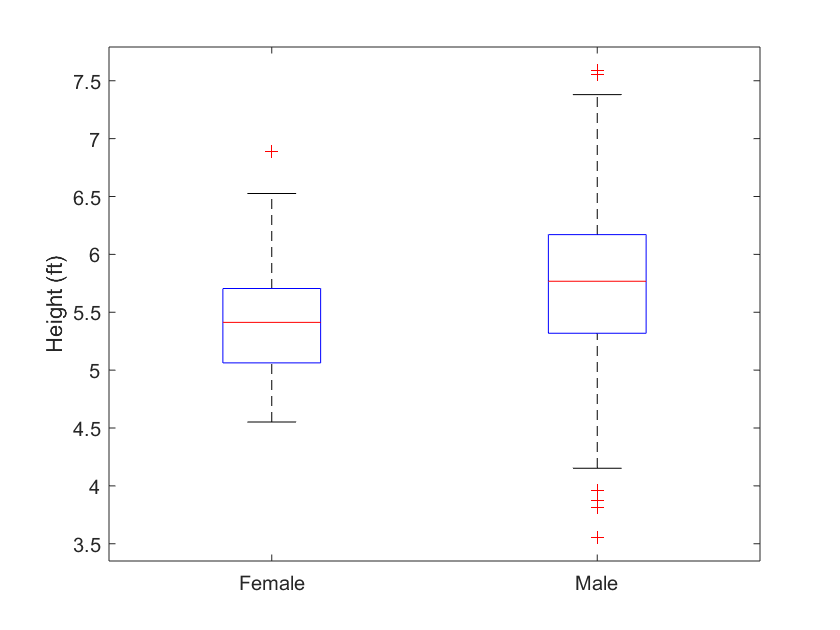

boxplot( data.height/12, data.gender ),  ylabel('Height (ft)')

## Is there a statistical difference between the heights of males and females?

[~,pvalue]=ttest2(data.height(I), data.height(~I))

pvalue = 2.6602e-04

if pvalue<=0.01
	fprintf('Yes, there is a statistical difference between the heights of males and females (p=%.1e)\n',pvalue);
else
	fprintf('No, there is no statistical difference between the heights of males and females (p=%.1e)\n',pvalue);
end

Yes, there is a statistical difference between the heights of males and females (p=2.7e-04)
